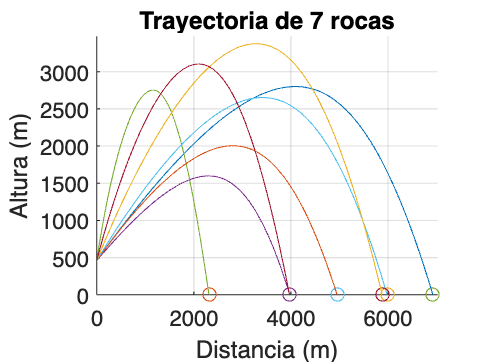

clc;
clear vars;
close all;

gravedad=-9.81;
numeroRocas=randi([3 10]);

densidadAire = 1.4; %kg/m3
densidadRoca = 2600;  %kg/m3
cDrag=1.54;
matrizRocas=[];
deltaT=0.2;
centroCrater=0;
prominencia=463;

% Ciclo que crea la matriz de los datos de cada
% roca, el orden es:
% vo, angulo, radio, área, volumen, masa
% coef B
limitex=0;
limitey=0;
for x = 1:numeroRocas
    listaTemporal=[];
    
    %Creación de valores aleatorios
    velRandom=randi([200 300]);
    anguloRandom=randi([30 80]);
    radioRandom= (randi([30 100]))/100;
    areaTemporal=pi*radioRandom^2;
    volumenTemporal=(4/3)*pi*radioRandom^3;
    masaTemporal=volumenTemporal*densidadRoca;
    coefBTemporal=0.5*densidadAire*cDrag*areaTemporal;
    %Se añaden a una lista temporal
    listaTemporal(end+1) = velRandom;
    listaTemporal(end+1) = anguloRandom;
    listaTemporal(end+1) = radioRandom;
    listaTemporal(end+1) = areaTemporal;
    listaTemporal(end+1) = volumenTemporal;
    listaTemporal(end+1) = masaTemporal;
    listaTemporal(end+1) = coefBTemporal;
    %Se añade a la matriz
    matrizRocas( end+1, : ) = listaTemporal;
end

for i = 1:numeroRocas
    anguloEnRadianes=deg2rad( matrizRocas(i,2) );
    cosenoAngulo=cos(anguloEnRadianes);
    senoAngulo=sin(anguloEnRadianes);

    acelx0=0;
    x0=centroCrater;
    velx0=matrizRocas(i,1)*cosenoAngulo;
    
    acely0=gravedad;
    y0=prominencia;
    vely0=matrizRocas(i,1)*senoAngulo;

    acelxnmenos1=0;
    xnmenos1=centroCrater-deltaT*velx0;
    velxnmenos1=0;
    
    acelynmenos1=0;
    ynmenos1=y0-(vely0*deltaT)+(0.5*gravedad*deltaT^2);
    velynmenos1=0;

    listaCalculoTemporalAcX=[];
    listaCalculoTemporalX=[];
    listaCalculoTemporalVelX=[];

    listaCalculoTemporalAcY=[];
    listaCalculoTemporalY=[];
    listaCalculoTemporalVelY=[];
    
    listaCalculoTemporalAcX(end+1) = acelxnmenos1;
    listaCalculoTemporalAcX(end+1) = acelx0;

    listaCalculoTemporalAcY(end+1) = acelynmenos1;
    listaCalculoTemporalAcY(end+1) = acely0;

    listaCalculoTemporalX(end+1) = xnmenos1;
    listaCalculoTemporalX(end+1) = x0;

    listaCalculoTemporalY(end+1) = ynmenos1;
    listaCalculoTemporalY(end+1) = y0;

    listaCalculoTemporalVelX(end+1) = velxnmenos1;
    listaCalculoTemporalVelX(end+1) = velx0;

    listaCalculoTemporalVelY(end+1) = velynmenos1;
    listaCalculoTemporalVelY(end+1) = vely0;
    ycalc=1;
    while ycalc>0
        axcalc=(-matrizRocas(i,7)*listaCalculoTemporalVelX(end)^2)/(matrizRocas(i,6));
        listaCalculoTemporalAcX(end+1)=axcalc;

        xcalc=2*listaCalculoTemporalX(end)-listaCalculoTemporalX(end-1)+0.5*listaCalculoTemporalAcX(end)*deltaT^2;
        listaCalculoTemporalX(end+1)=xcalc;
        
        if xcalc>limitex
           limitex=xcalc;
        end

        vxcalc=(listaCalculoTemporalX(end)-listaCalculoTemporalX(end-1))/deltaT;
        listaCalculoTemporalVelX(end+1)=vxcalc;

        aycalc=-(listaCalculoTemporalVelY(end)/abs(listaCalculoTemporalVelY(end)))*(matrizRocas(i,7)*(listaCalculoTemporalVelY(end)^2)/matrizRocas(i,6))+gravedad;
        listaCalculoTemporalAcY(end+1)=aycalc;

        ycalc=(2*listaCalculoTemporalY(end)-listaCalculoTemporalY(end-1))+(0.5*listaCalculoTemporalAcY(end)*deltaT^2);
        if ycalc>limitey
           limitey=ycalc;
        end
        if ycalc<0
           ycalc=0;
        end

        listaCalculoTemporalY(end+1)=ycalc;

        vycalc=(listaCalculoTemporalY(end)-listaCalculoTemporalY(end-1))/deltaT;
        listaCalculoTemporalVelY(end+1)=vycalc;
    end
    tituloGrafica= strcat("Trayectoria de ", num2str(numeroRocas)," rocas");
    xlabel('Distancia (m)');
    ylabel('Altura (m)');
    title( tituloGrafica );
    grid on;
    
    

    xlim([0 (limitex+100)])
    ylim([0 (limitey+100)])
    hold on;
    comet(listaCalculoTemporalX, listaCalculoTemporalY);
    plot(listaCalculoTemporalX,listaCalculoTemporalY);

    
    
end